rotx = @(radians) [1,0,0;
                   0,cos(radians),-sin(radians);
                   0,sin(radians),cos(radians)];
               
roty = @(radians) [cos(radians),0,sin(radians);
                   0,1,0;
                   -sin(radians),0,cos(radians)];
               
rotz = @(radians) [cos(radians), -sin(radians), 0;
                   sin(radians), cos(radians),0;
                   0,0,1];
               
d2r = @(degree) degree*pi/180;

a = rotx(d2r(45));
b = roty(d2r(45));

pose = [2,3,-1,a(1,3),a(2,3),a(3,3)];
offset = [1,1,1];
offset_orientation = [];

out = zeros([1,5]);
out(4) = acos(pose(6)); 
out(5) = atan2(pose(4),-pose(5));
out(1) = cos(out(5))*(pose(1)-offset(1)) + sin(out(5))*(pose(2)-offset(2));
out(2) = -sin(out(5))*cos(out(4))*(pose(1)-offset(1)) +...
        cos(out(5))*cos(out(4))*(pose(2)-offset(2)) + ...
        sin(out(4))*(pose(3)-offset(3));
out(3) = sin(out(5))*sin(out(4))*(pose(1)-offset(1)) -...
        cos(out(5))*sin(out(4))*(pose(2)-offset(2)) + ...
        cos(out(4))*(pose(3)-offset(3));

% Forward Kinematics
syms X Y Z A C I J K real
O = [sin(C)*sin(A);
    -cos(C)*sin(A);
    cos(A)];

Q = [cos(C)*X-sin(C)*cos(A)*Y+sin(C)*sin(A)*Z+I;
    sin(C)*X+cos(C)*cos(A)*Y-cos(C)*sin(A)*Z+J;
    sin(A)*Y+cos(A)*Z+K];

O = vpa(subs(O,'A',out(4)));
O = vpa(subs(O,'C',out(5)));

Q = vpa(subs(Q,'X',out(1)));
Q = vpa(subs(Q,'Y',out(2)));
Q = vpa(subs(Q,'Z',out(3)));
Q = vpa(subs(Q,'I',offset(1)));
Q = vpa(subs(Q,'J',offset(2)));
Q = vpa(subs(Q,'K',offset(3)));
Q = vpa(subs(Q,'A',out(4)));
Q = vpa(subs(Q,'C',out(5)));

#### Operational Space Path Control

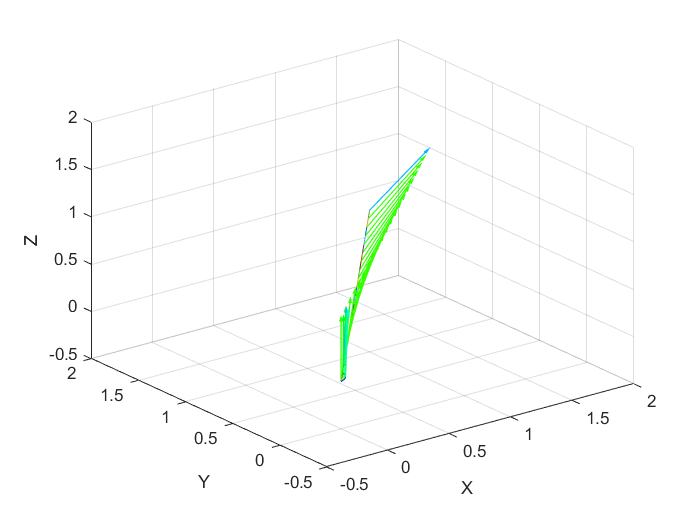

a = roty(d2r(45));
pose = [1,1,1,0.707,0,0.707];
offset = [0,0,0].';

% segment poses
num_seg = 20;
axis_vec = [-0.5,2,-0.5,2,-0.5,2];
figure;
pos_seg = zeros([3,num_seg]);
ori_seg = zeros([3,num_seg]);
pose_seg = zeros([6,num_seg]);
for i = 1:num_seg
    pos_seg(1:3,i) = (i).*pose(1:3).'./num_seg;
    rot_manual = roty(d2r((i)*45/num_seg));
    ori_seg(1:3,i) = rot_manual(:,3);
    pose_seg(:,i) = [pos_seg(:,i);ori_seg(:,i)];
    if i==1
        [joints,rot] = Inv_kin(pose_seg(:,i).',[0,0,0,0,0,1].',eye(3,3));
        [O,Q] = forKinPlot(joints,[0,0,0],pose_seg(:,i),[0,0,0,0,0,1].',eye(3,3),axis_vec,0.7,10);
        hold on;
    else
        prev_rot = rot;
        [joints,rot] = Inv_kin(pose_seg(:,i).',pose_seg(:,i-1).',prev_rot);
        [O,Q] = forKinPlot(joints,pose_seg(1:3,i-1),pose_seg(:,i),pose_seg(:,i-1),prev_rot,axis_vec,0.7,51);
        hold on;
    end
end